%% Fit Host Chemical Shift: H2, H3, G2, HG2 (H:G=1:2)
clear; clc;

%% Known Constants
KH2 = 0.14;     % M^-1
KH3 = 440;     % M^-2
KG2 = 15.1;     % M^-1

% Experimental total concentrations (mol/L)
Gtot = [0.25, 1, 2, 3, 4 ,5, 6, 7.5]' * 1e-3; % Guest total conc. (in M)
Htot = [0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5]' * 1e-3;      % Fixed Host total conc. (in M)
delta_obs_exp = [8.8770, 8.8747, 8.8717, 8.8693, 8.8662, 8.8634, 8.8607, 8.8566]'; % Replace with real data


%% Initial Guess: [logK1, logK2, δ_H, δ_H2, δ_H3, δ_HG, δ_HG2]
params0 = [-1, 2, 8.67, 8.67, 8.6, 8, 8];
lb = [-5, -5, 8, 8, 8, 7, 7];
ub = [10, 10, 8.9, 8.9, 8.9, 8.9, 8.9];

%% Fit
options = optimoptions('lsqcurvefit','Display','iter','TolFun',1e-9,'TolX',1e-9);
[params_fit,~,~,~,~,~,~] = lsqcurvefit( ...
    @(p,x) model_host_shift_stepwise(p,x,KH2,KH3,KG2), ...
    params0, [Htot Gtot], delta_obs_exp, lb, ub, options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          8          0.313217                            0.364
     1         16         0.0683814         1.61385            0.092      
     2         24         0.0126404        0.150143           0.0225      
     3         32        0.00188164         0.88678          0.00514      
     4         40       0.000427714        0.158963          0.00091      
     5         48       0.000346803        0.153951         6.82e-05      
     6         56        0.00034604        0.135692         7.08e-06      
     7         64       0.000345999       0.0578468         6.79e-06      
     8         72       0.000345951       0.0612624         6.56e-06      
     9         80       0.000251864         1.24674         0.000644      
    10         88       0.000251864         1.03843         0.000644      
    11         96       0.000114288      

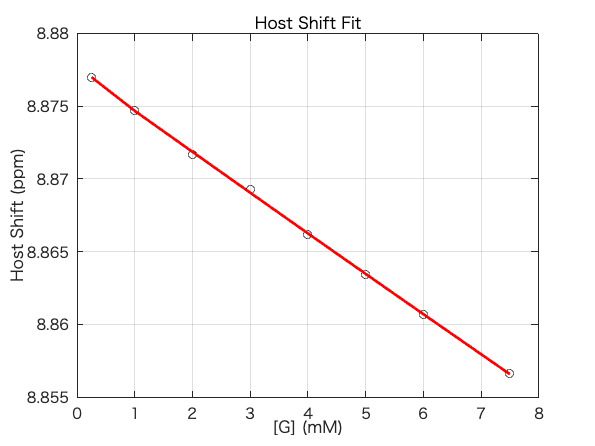


%% Plot
delta_fit = model_host_shift_stepwise(params_fit,[Htot Gtot],KH2,KH3,KG2);
figure;
plot(Gtot*1e3, delta_obs_exp, 'ko'); hold on;
plot(Gtot*1e3, delta_fit, 'r-', 'LineWidth', 2);
xlabel('[G] (mM)'); ylabel('Host Shift (ppm)');
title('Host Shift Fit'); grid on;


fprintf('Fitted log10(K1) = %.2f\n', params_fit(1));

Fitted log10(K1) = 0.53


fprintf('Fitted log10(K2) = %.2f\n', params_fit(2));

Fitted log10(K2) = 1.56



% Calculate R-squared
SS_res = sum((delta_obs_exp - delta_fit).^2);
SS_tot = sum((delta_obs_exp - mean(delta_obs_exp)).^2);
R_squared = 1 - (SS_res / SS_tot);

% Display R-squared
fprintf('R-squared: %.6f\n', R_squared);

R-squared: 0.999721


function delta_obs = model_host_shift_stepwise(params, xdata, KH2, KH3, KG2)
    K1 = 10^params(1);
    K2 = 10^params(2);
    delta_H = params(3);
    delta_H2 = params(4);
    delta_H3 = params(5);
    delta_HG = params(6);
    delta_HG2 = params(7);

    N = size(xdata,1);
    delta_obs = zeros(N,1);

    for i = 1:N
        Ht = xdata(i,1);
        Gt = xdata(i,2);

        x0 = [Ht/2, Gt/2, 1e-6*ones(1,5)]; % [H G HG HG2 H2 H3 G2]
        sol = fsolve(@(x) system_eqs_stepwise(x, Ht, Gt, KH2, KH3, KG2, K1, K2), ...
                     x0, optimoptions('fsolve','Display','off'));
        H = sol(1); H2 = sol(5); H3 = sol(6); HG = sol(3); HG2 = sol(4);

        num = H*delta_H + 2*H2*delta_H2 + 3*H3*delta_H3 + HG*delta_HG + HG2*delta_HG2;
        denom = H + 2*H2 + 3*H3 + HG + HG2;
        delta_obs(i) = num / denom;
    end
end


function F = system_eqs_stepwise(x, Htot, Gtot, KH2, KH3, KG2, K1, K2)
    % x = [H, G, HG, HG2, H2, H3, G2]
    H = x(1); G = x(2); HG = x(3); HG2 = x(4);
    H2 = x(5); H3 = x(6); G2 = x(7);

    % Equilibria
    F(1) = H2 - KH2 * H^2;
    F(2) = H3 - KH3 * H * H2;
    F(3) = G2 - KG2 * G^2;
    F(4) = HG - K1 * H * G;
    F(5) = HG2 - K2 * HG * G;

    % Mass balances
    F(6) = Htot - (H + 2*H2 + 3*H3 + HG + HG2);
    F(7) = Gtot - (G + 2*G2 + HG + 2*HG2);
end

